% Data import and categorization.
  A=[92.12811753495609 8135 1;
   52.372581043370793 1629 1;
   49.320215545456612 2824 1;
   195.82116711759434 9780 0;
   100.80193659982224 8856 1;
   113.71113387918105 10387 1;
   54.587980520593121 4002 1;
   216.13369216830267 9572 0;
   122.33448745905834 9177 1;
   198.17621607581896 9304 0;
   71.067735543226377 5354 1;
   129.52240191677302 6405 0;
   121.49993662088163 10135 1;
   144.08134536999512 6977 0;
   32.119065165757 1068 1;
   93.511984578003009 3723 0;
   63.583074181200146 2374 0;
   97.6261727455732 8086 1;
   47.583103616512247 1415 0;
   90.036272256417249 5367 1;
   183.36046674761221 7803 0;
   100.41539984998558 6517 1;
   54.847602872506812 2779 1;
   56.374196858062454 1855 0;
   47.770960250407285 2867 1;
   64.211107915749068 4687 1;
   121.97824778980936 10310 1;
   88.592364609991748 7966 1;
   47.17971290231803 2663 1;
   90.611225724112714 8735 1;
   76.3973729599586 5132 1;
   168.70097729078248 8086 0;
   88.816188289405659 4321 0;
   75.797597102062014 6510 1;
   223.0378574579876 10964 0;
   157.12805990787081 7671 0;
   202.06255075414697 9889 0;
   113.41940077958014 4582 0;
   120.73800292419928 5340 0;
   79.198725340944179 8330 1;
   132.9931132644225 10945 1;
   74.088756509257379 5766 1;
   66.484975397869846 4315 1;
   142.64882141763508 7053 0;
   97.005863387471734 8731 1;
   75.214063406839642 4856 1;
   36.092260757293921 3038 1;
   116.73429818522619 4866 0;
   67.629764068451223 1650 0;
   114.02922486622516 5323 0];

y=A(:,1);
x1=A(:,2);
x2=A(:,3);

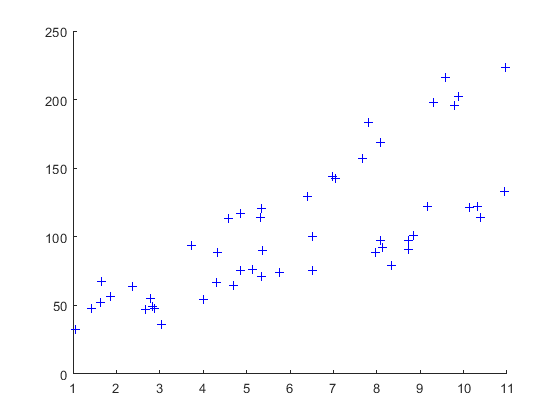

z1 = x1./1000;
scatter(z1, y, 'blue', '+');

regr_1 = regstats(y, [z1, x2], 'linear', 'all');
regr_1.rsquare;

ans =          0.891927966349476


beta1 = regr_1.beta;

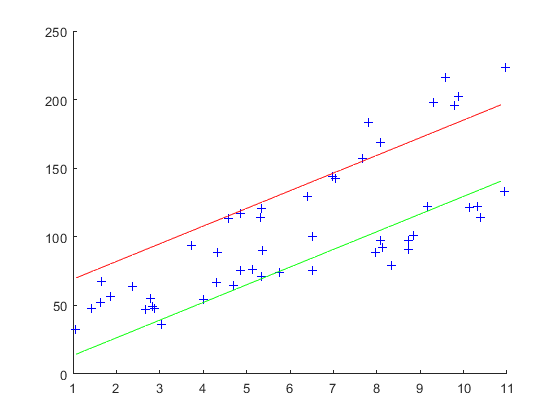

scatter(z1,y,'blue', '+');
hold on;
z11=1.068:0.1:10.964;
y1=beta1(1)+beta1(2)*z11;
y2=beta1(1)+beta1(2)*z11+beta1(3);
plot(z11,y1, 'red')
hold on;
plot(z11,y2, 'green')
hold off;

z2 = x2.*z1;
regr_2 = regstats(y, [z1, z2]);
regr_2.rsquare;

regr_2.beta

ans =           24.2080563109949
          18.1452199996685
         -9.10731452957804



K = inv(X'*X)

K =         0.0889084946938491        -0.022487266281628       -0.0177650620940997       0.00458213072862082
        -0.022487266281628        0.0594163559932237       0.00827591924116465      -0.00646043472015539
       -0.0177650620940997       0.00827591924116465       0.00802715145929538      -0.00234373365972265
       0.00458213072862082      -0.00646043472015539      -0.00234373365972265       0.00110050903962559


sqt = K(3,3)

sqt =        0.00802715145929538


s = sqrt(regr_2.fstat.sse/(50-2-1))

s =           9.07018583697459


t = 2.01;



lowerbound = -9.11-t*s*sqt

lowerbound =          -9.25634358850948


upperbound = -9.11+t*s*sqt

upperbound =          -8.96365641149052
